# Variable Viewer

Copyright 2023-2024 The MathWorks, Inc.

The Variable Viewer can be used to check the results of the initialization for the model. It allows to check, if individual intial value targets for variables have been satisfied. 

Use the Variable Viewer to check the models' initial conditions with their priorities, explore issues when model initialization fails or throws warnings. 

openExample('simscapeelectrical/PMSMTractionDriveExample') 

Open the Variable Viewer:

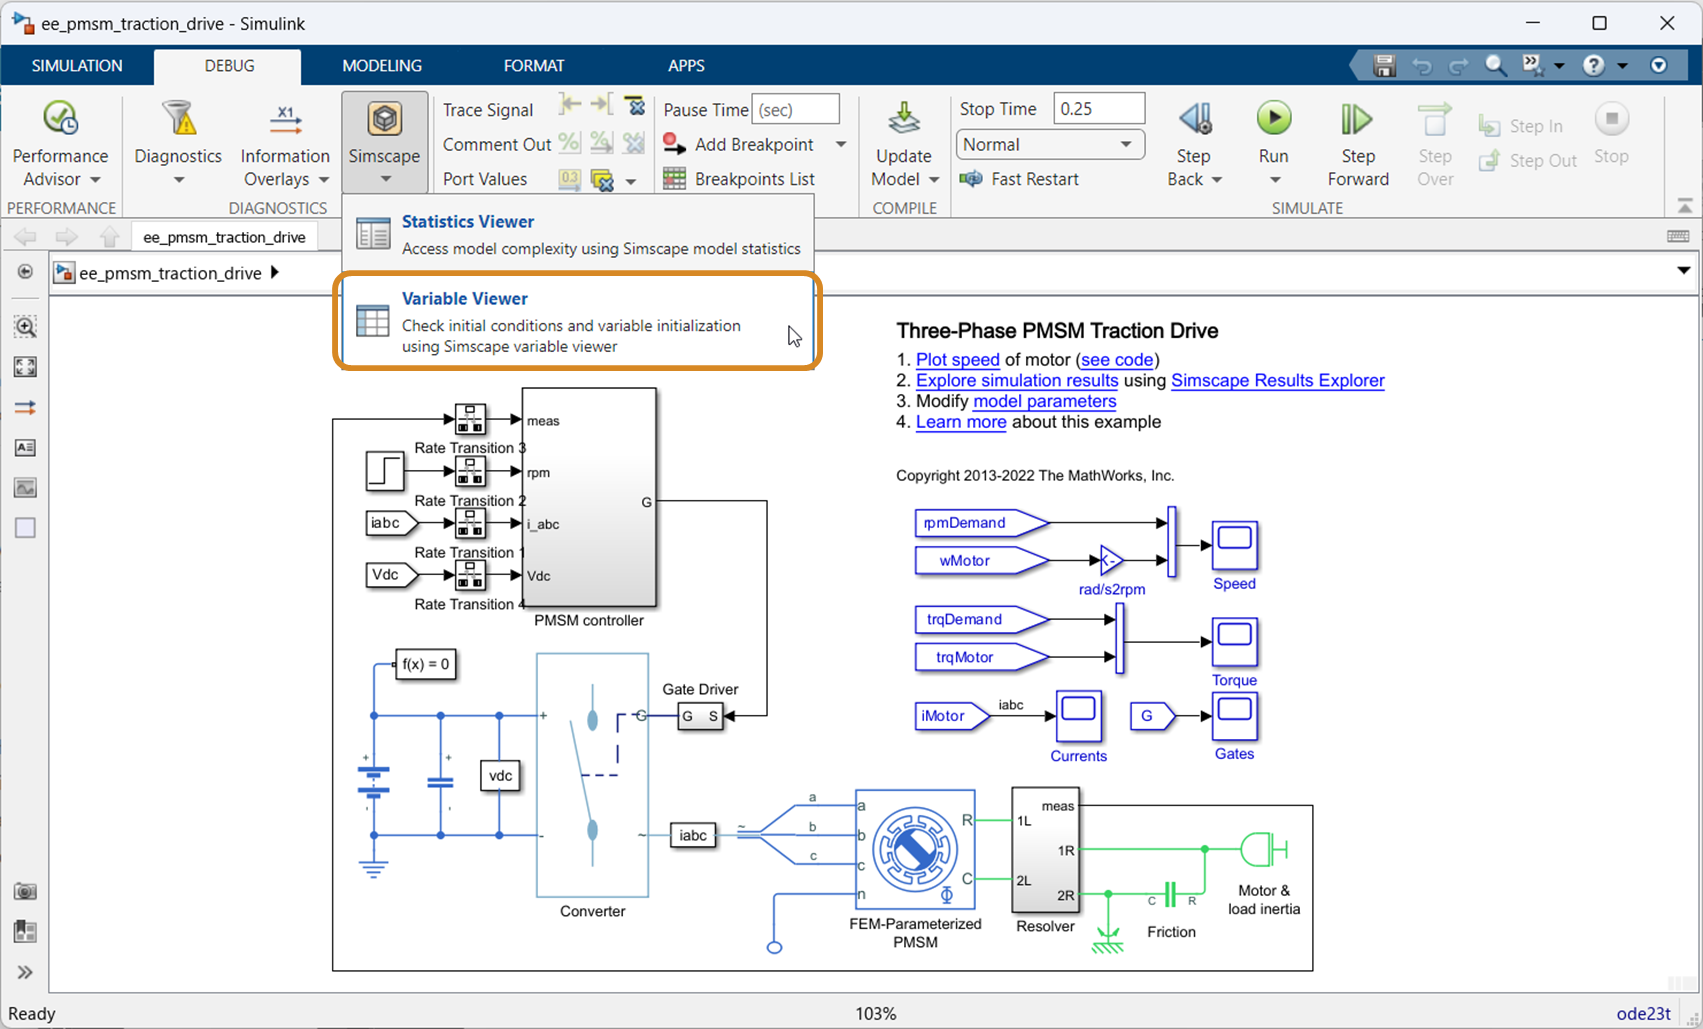

If the model did not run prior to opening the Variable Viewer, it won't contain any data. Do a  *Update* to populate the window with the initialization information:

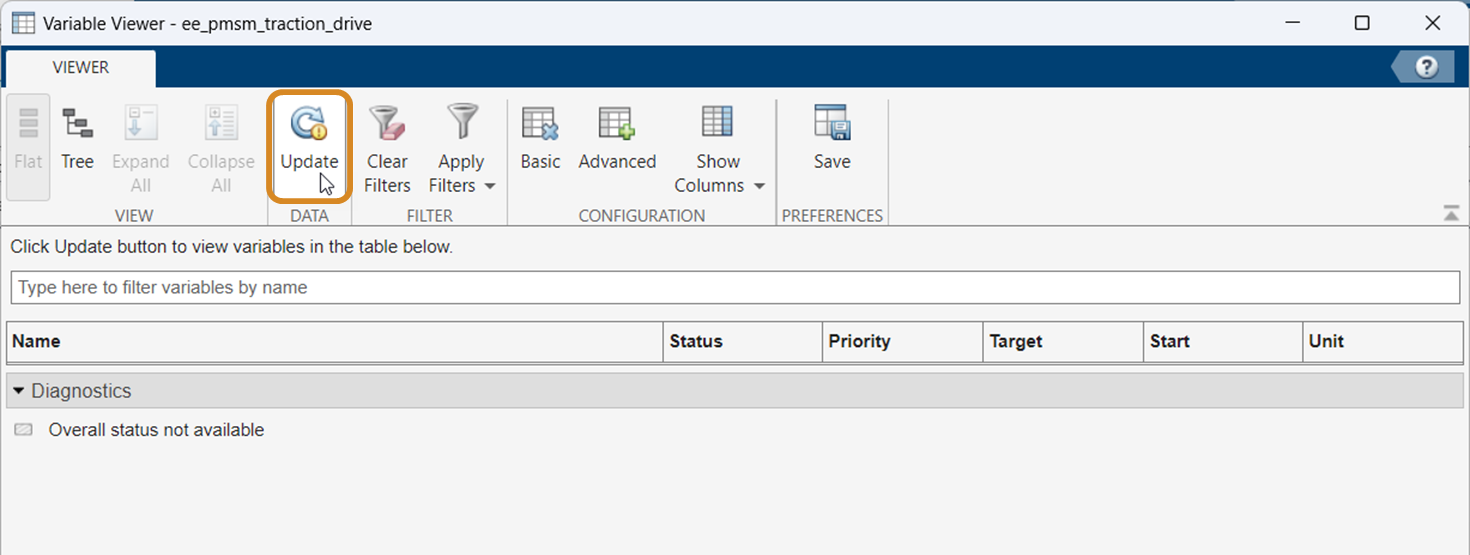

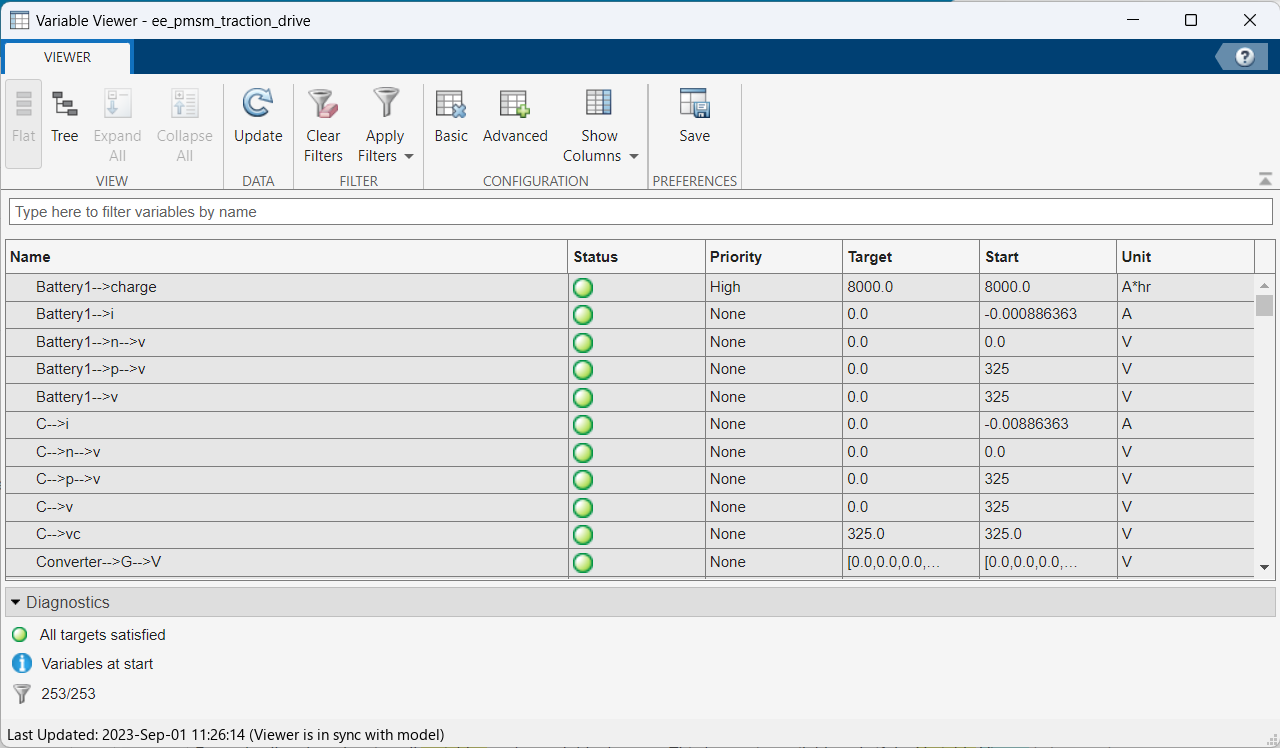

The report lists all Simscape componentes in the model with all it's public variables. The columns display information about initialization status, variable priority, target and acutal initial values. 

The *Status *column indicates the initialization status of the different variables, it can be: 

- Green circle: Variables with targets satisfied or for variables with no initialization priority

- Yellow triangle: Low-priority targets that have not been satisfied

- Red square: High-priority targets that have not been satsfied

- Red cross: In case initial conditions cannot be solved, this is displayes for variables that could not be satisfied

- Gray rectangle: Status is not available

The *Priority *column displays the variables initialization priority, either specified via block interface or in the underlying component file. Read more in [Variable Initialization Priority](https://www.mathworks.com/help/releases/R2023a/simscape/ug/block-level-variable-initialization.html#bt_tvnk-1)

*Target* and *Start* columns displays the target and the actual start values for variables. The *Unit* colums lists the variables base unit. 

You can right-click any variable node in the Variable Viewer and select *Go to block* to navigate to the model component where the variable initial values are defined. 

Different settings can help with navigating the Variable Viewer. Use the *Tree* view to have the variables grouped within parent port, block. and subsystem. The Advanced view will add more variable information in aditional columns:

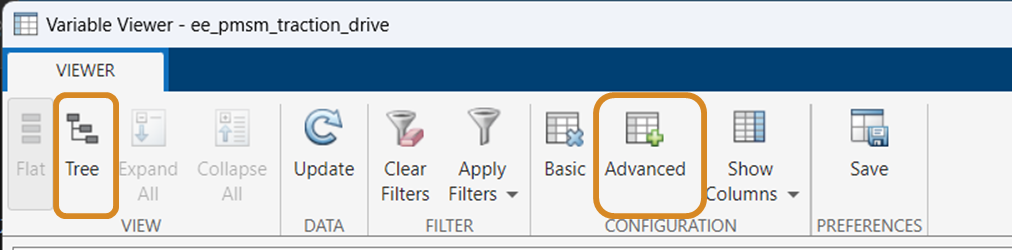

It is good practice to ensure that differential variables have a high-priority values. You can make use *Apply Filters *to search for variables according to specific conditions, for example for differential values with high-priority initial targets:

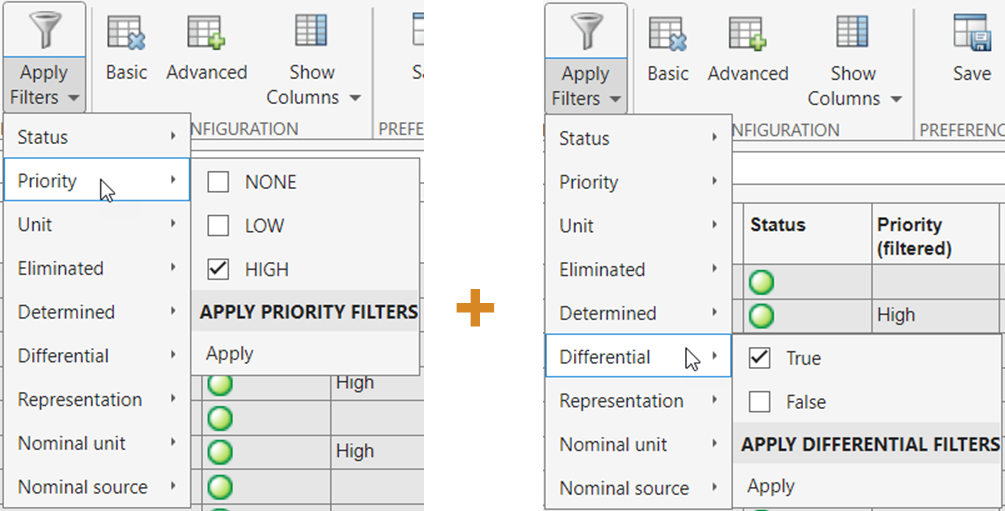

You can use Save to save the current Variable Viewer configuration settings. The next time you open the Variable Viewer it will open with the same settings. 